%% Sugeno Hierarchical Fuzzy Aging Model

% Load fuzzy inference systems
fis1 = readfis('fis1_power_startupdelay_electricalstress.fis');
fis2 = readfis('fis2_harmonics_usage_thermalstress.fis');
fis3 = readfis('fis3_thermalstress_electricalstress.fis');

fuzzyLogicDesigner(fis1)
fuzzyLogicDesigner(fis2)
fuzzyLogicDesigner(fis3)

% Test multiple scenarios
test_cases = [
    450 1 3 2;
    900 4 7 5;
    1800 7 13 8
];

for i = 1:size(test_cases,1)
    
    % Extract inputs
    P = test_cases(i,1); % power (watts)
    S = test_cases(i,2); % startup delay (seconds)
    H = test_cases(i,3); % harmonics THD (%)
    U = test_cases(i,4); % usage index
    
    % Stage 1
    E = evalfis(fis1, [P S]);

    % Stage 2
    T = evalfis(fis2, [H U]);

    % Stabilization
    E = max(min(E, 99.999), 0.001);
    T = max(min(T, 99.999), 0.001);

    % Final stage
    HS = evalfis(fis3, [E T]);

    % Classification
    if HS >= 75
        condition = "Healthy";
    elseif HS >= 45
        condition = "Aging";
    else
        condition = "Failure";
    end
    
    % Display
    fprintf('\n')
    fprintf("\n\n\nTest Case %d:\n", i)
    fprintf("Inputs: Power=%dW StartupDelay=%.1fs Harmonics=%d%% Usage=%d\n", P,S,H,U)
    fprintf("Electrical Stress = %.2f\n", E)
    fprintf("Thermal Stress = %.2f\n", T)
    fprintf("Health Score = %.2f → %s\n", HS, condition)
end




Test Case 1:


Inputs: Power=450W StartupDelay=1.0s Harmonics=3% Usage=2


Electrical Stress = 20.00


Thermal Stress = 20.00


Health Score = 90.00 → Healthy





Test Case 2:


Inputs: Power=900W StartupDelay=4.0s Harmonics=7% Usage=5


Electrical Stress = 50.00


Thermal Stress = 50.00


Health Score = 60.00 → Aging





Test Case 3:


Inputs: Power=1800W StartupDelay=7.0s Harmonics=13% Usage=8


Electrical Stress = 80.00


Thermal Stress = 80.00


Health Score = 30.00 → Failure


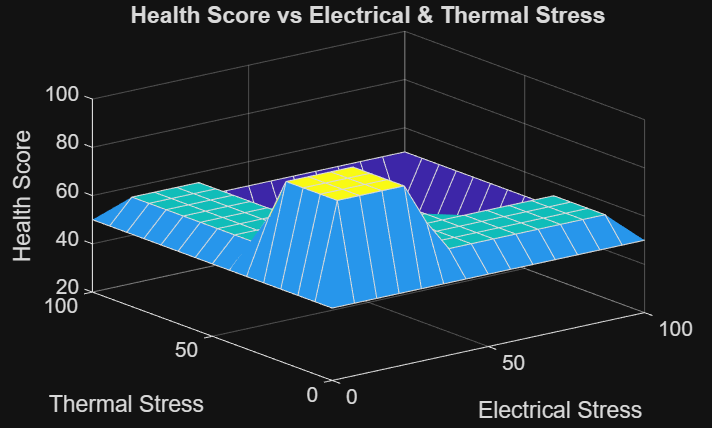

%graph
figure
gensurf(fis3)
title('Health Score vs Electrical & Thermal Stress')
xlabel('Electrical Stress')
ylabel('Thermal Stress')
zlabel('Health Score')


%simulation with block diagrams
open_system('blockdiag.slx')